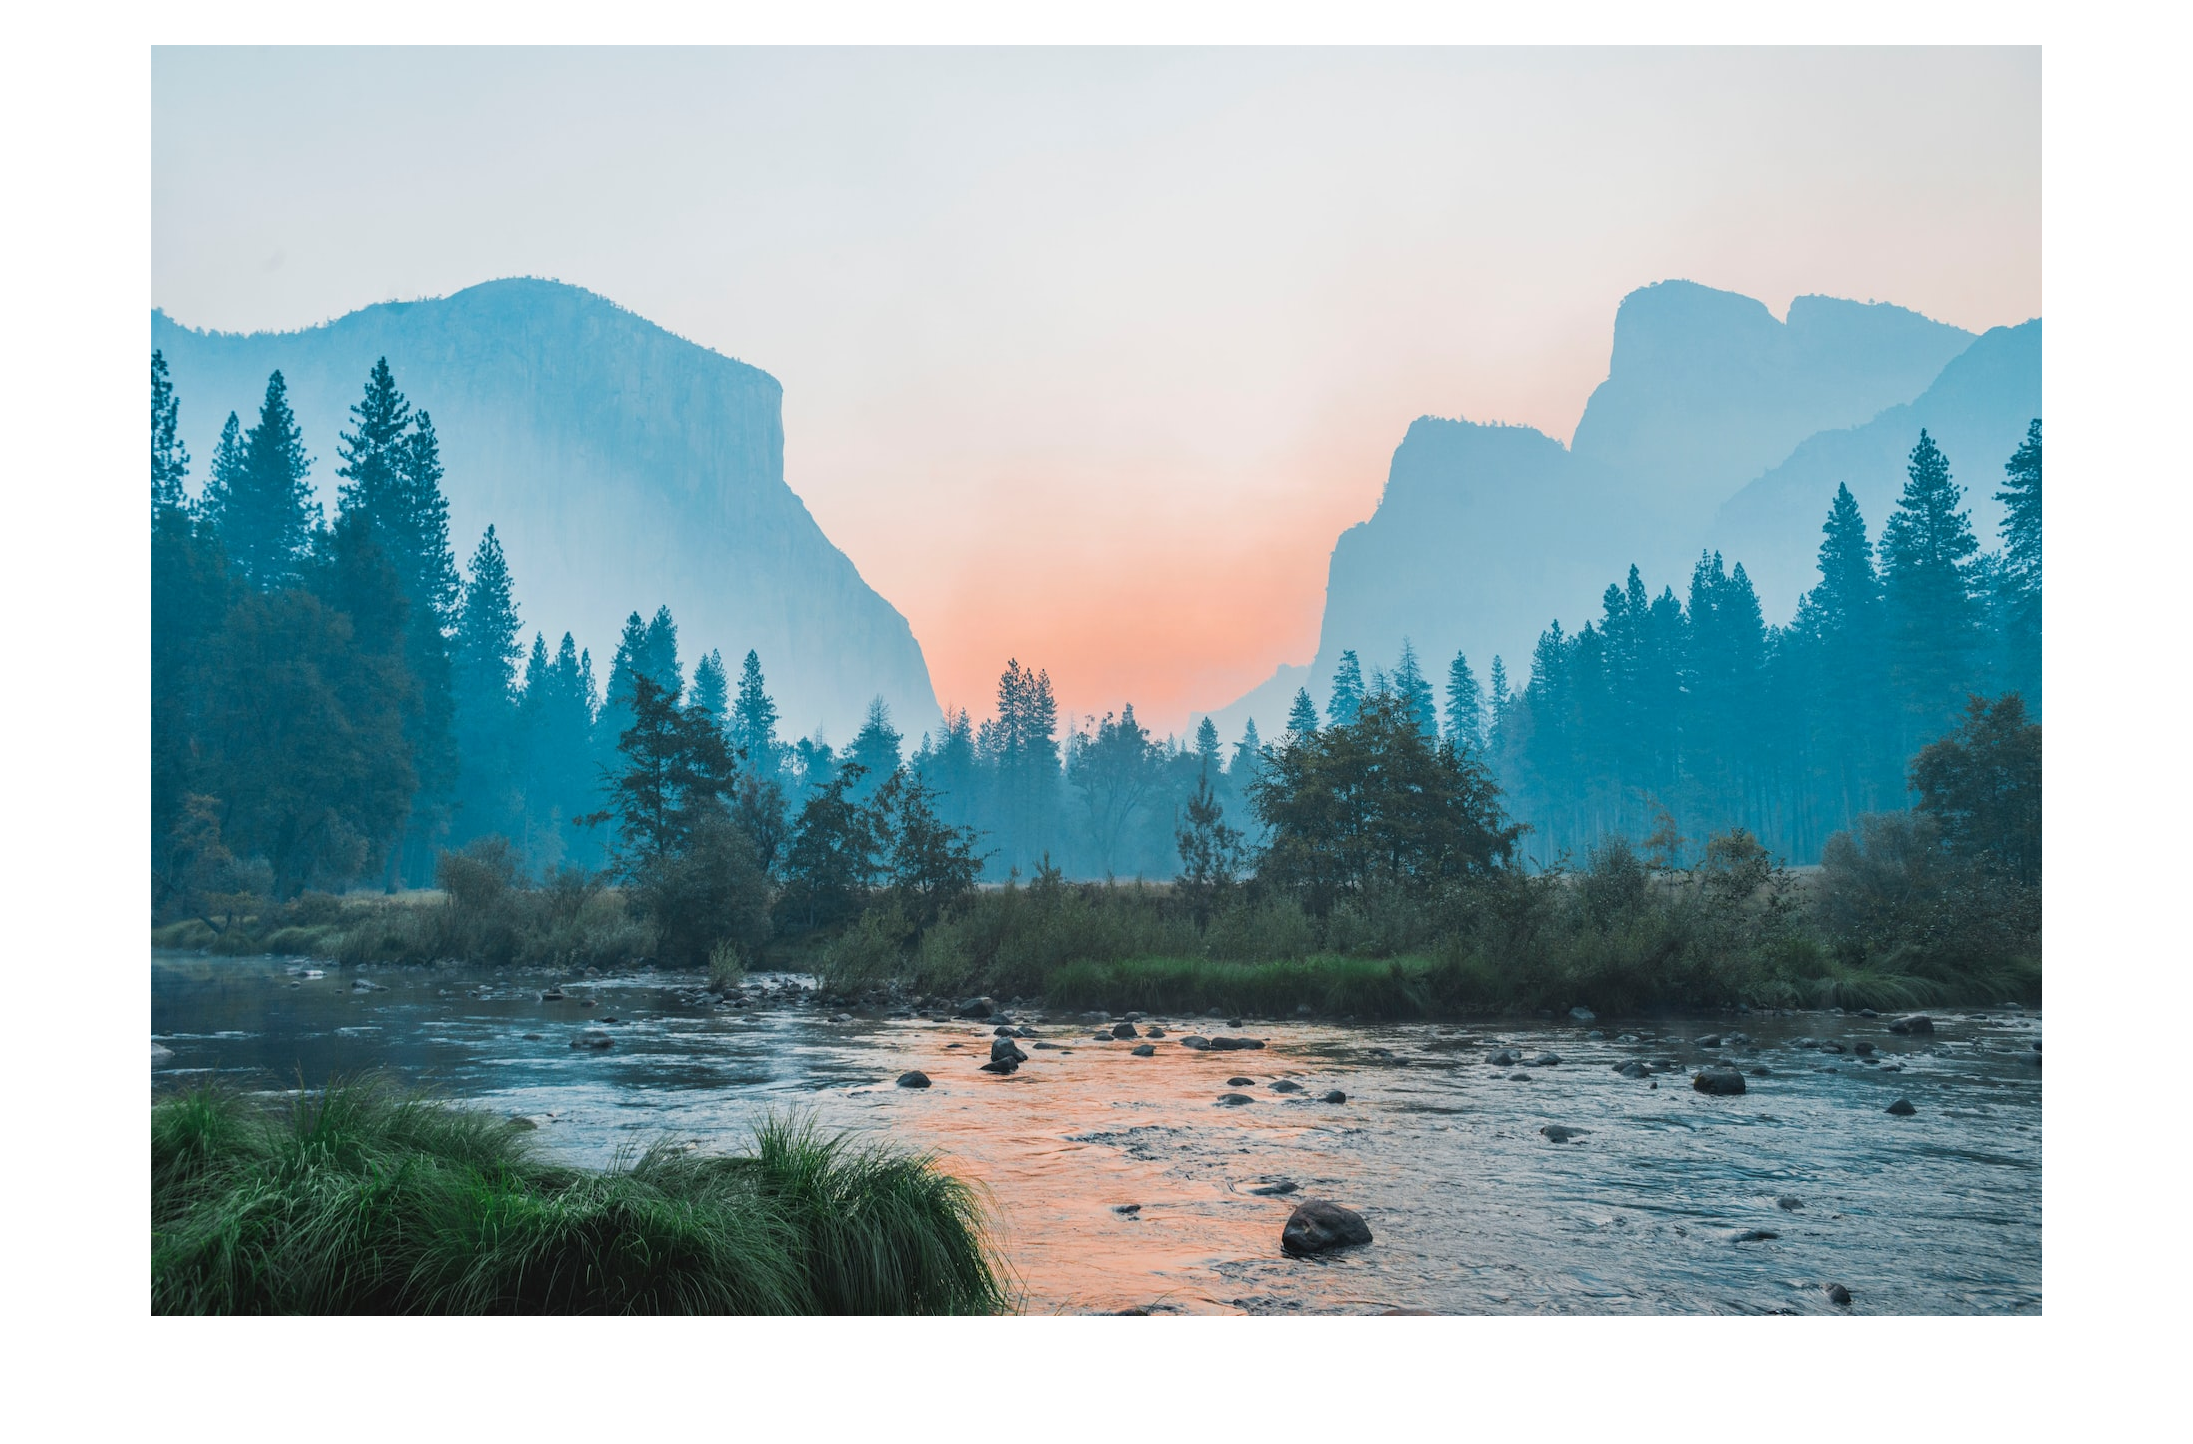

% Load in an image
im = imread('.\images\bailey-zindel.jpg');
im_size = size(im); % Check size of image
pearl_size = 31; % Diameter of the pearl
% Not the whole iamage, so the image and reproduced image will be the same size
% dependent on the pearl diamter
im2 = im(1:floor(im_size(1)/pearl_size)*pearl_size, 1:floor(im_size(2)/pearl_size)*pearl_size,:);
imshow(im2)

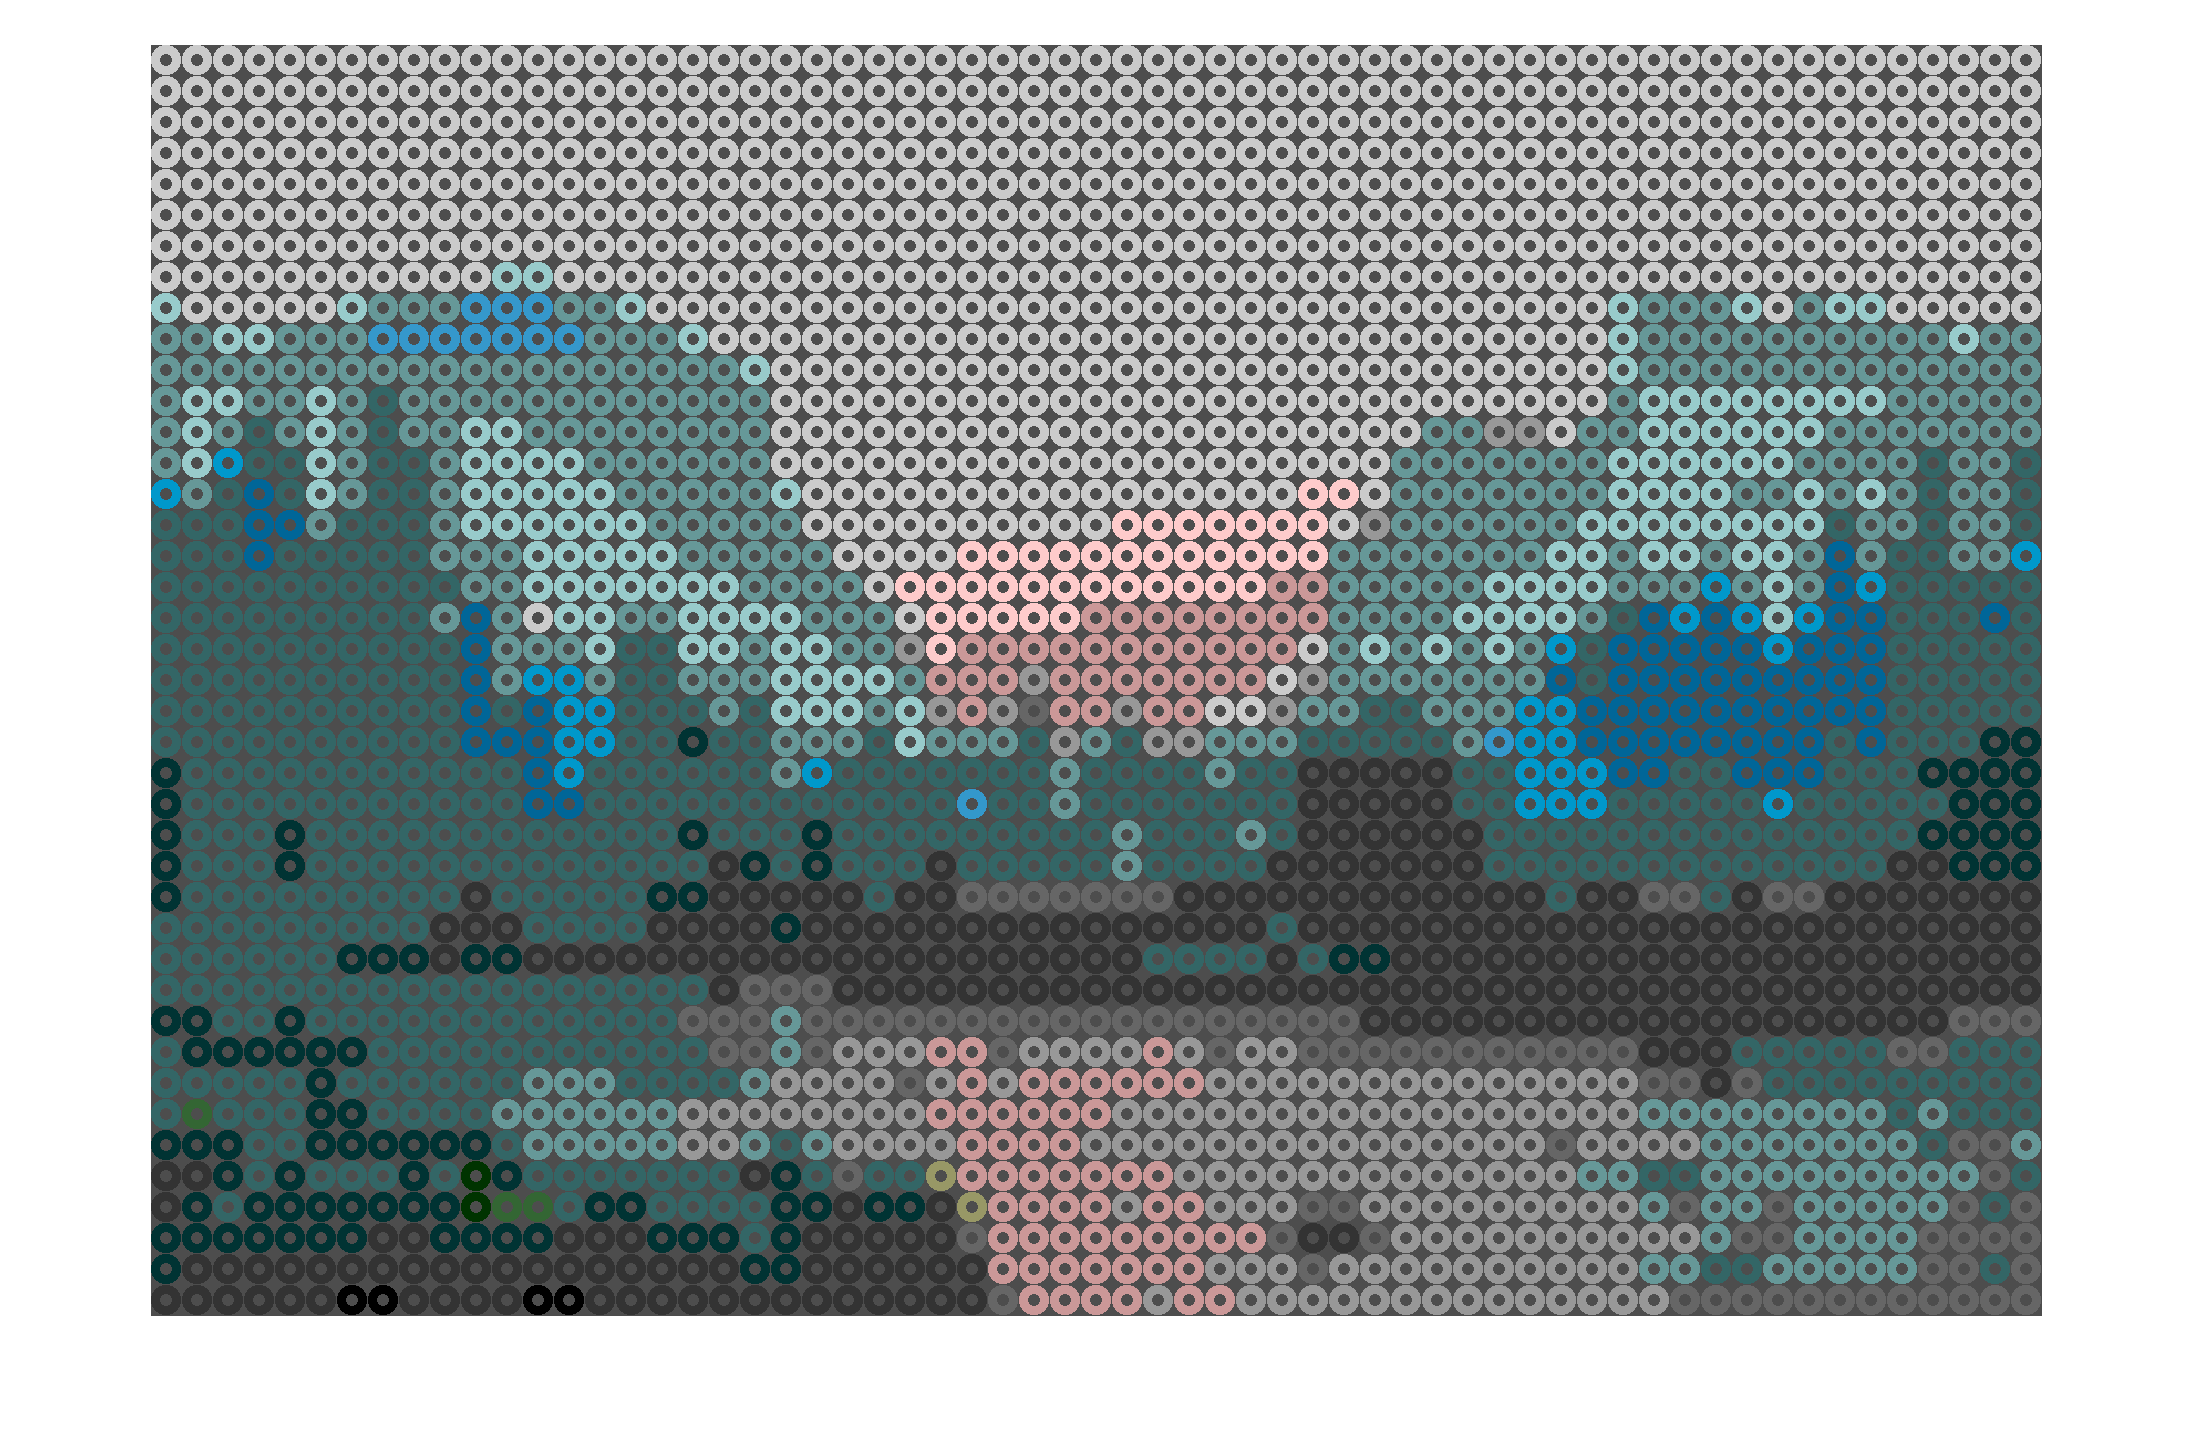

% Reproduce it to pearls
% Set the background color behind the pearls
% Dont set the color to 1, cause then the code won't work!
b_color = 0.3;
% Color spectrum:
% 1. HTML colors
% 2. Optimised HTML colors
% 3. Randomised Colors
% 4. Colors dependent on the image 
o_color = 4; % Color option
image = drawMultiplePearls2(im2, pearl_size,b_color, o_color);
imshow(image)

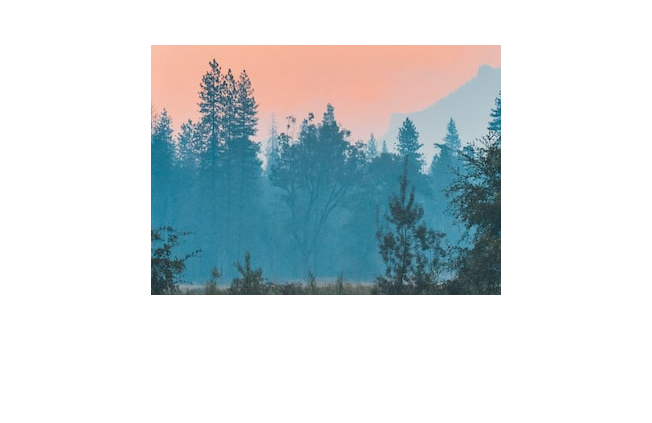

% Testing for a smaller image
im_small = im(600:850, 800:1150,:);
im_small = im_small(1:250, 1:350, :); % Remove last row and col?
imshow(im_small)

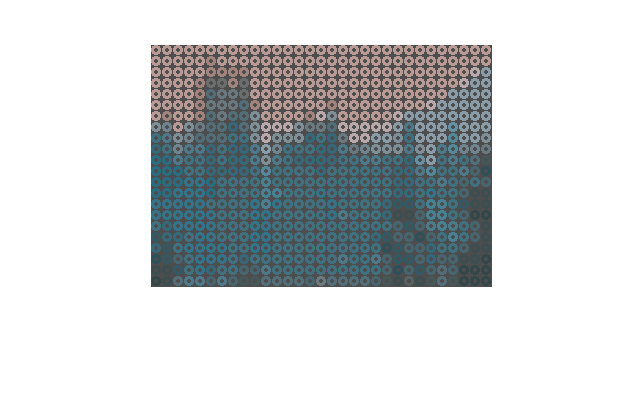

pearl_diameter = 11; % diameter of the pearl, should be based on the size of the image
% Creates the matrix with all the pearls
op_color = 4;
pearls = drawMultiplePearls2(im_small,pearl_diameter,b_color, op_color); % Send in image and diameter of pearl
imshow(pearls) % Show the image

% Kmeans
[L, C] = imsegkmeans(im, 54);

J = label2rgb(L, im2double(C));
imshow(J)

% C is the 54 colors in RGB 
C3 = im2double(C)
C

C2 = C/255